%% データの読み込み
sub = 10; % 被験者の指定
filename = ['../../../materials/alpha_data_tsss/' 'sub' num2str(sub) '_alpha_data_tsss'];
dummy = ['load ' filename ' data_*'];
eval(dummy);

%% データの分割
cfg = [];
cfg.showcallinfo = 'no';
cfg.length = 2; % 2秒の時間窓
cfg.overlap = 0.5; % 時間窓のオーバーラップの割合 (この場合2秒*0.5=1秒)
data_o_crop = ft_redefinetrial(cfg, data_o);

the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials


data_c_crop = ft_redefinetrial(cfg, data_c);

the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials


%% FFT
cfg = [];
cfg.method = 'mtmfft';
cfg.showcallinfo = 'no';
cfg.taper = 'hanning';
cfg.output = 'pow';
FFT_o = ft_freqanalysis(cfg, data_o_crop);

the input is raw data with 204 channels and 174 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 174/174 nfft: 2000 samples, datalength: 2000 samples, 1 tapers



FFT_c = ft_freqanalysis(cfg, data_c_crop)

the input is raw data with 204 channels and 174 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 174/174 nfft: 2000 samples, datalength: 2000 samples, 1 tapers



FFT_c = フィールドをもつ struct :
        label: {204×1 cell}
       dimord: 'chan_freq'
         freq: [0 0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6 6.5000 7 7.5000 8 8.5000 9 9.5000 10 10.5000 11 11.5000 12 12.5000 13 13.5000 14 14.5000 15 15.5000 16 16.5000 17 17.5000 18 18.5000 19 19.5000 20 20.5000 21 … ] (1×1001 double)
    powspctrm: [204×1001 double]
         grad: [1×1 struct]
          cfg: [1×1 struct]


cfg = [];
cfg.channel = {'MEGGRAD'};
cfg.combinemethod = 'sum';
cfg.showcallinfo = 'no';
FFT_o_cmb = ft_combineplanar(cfg, FFT_o);

the input is freq data with 204 channels, 1001 frequencybins and no timebins


FFT_c_cmb = ft_combineplanar(cfg, FFT_c);

the input is freq data with 204 channels, 1001 frequencybins and no timebins


[tmp, index] = sort(mean(FFT_o_cmb.powspctrm(:,8<FFT_o_cmb.freq&FFT_o_cmb.freq<13).'), 'descend');

   1.0e-23 *

    0.1806    0.1543    0.1449    0.1384    0.1341    0.1136    0.1096    0.0978    0.0931    0.0879    0.0878    0.0852    0.0845    0.0791    0.0776    0.0765    0.0759    0.0716    0.0716    0.0707    0.0696    0.0694    0.0684    0.0631    0.0630    0.0624    0.0616    0.0616    0.0604    0.0585    0.0538    0.0532    0.0526    0.0493    0.0488    0.0468    0.0461    0.0453    0.0446    0.0440    0.0434    0.0434    0.0432    0.0428    0.0415    0.0409    0.0403    0.0397    0.0384    0.0371    0.0353    0.0352    0.0350    0.0347    0.0342    0.0341    0.0322    0.0320    0.0317    0.0309    0.0308    0.0308    0.0307    0.0299    0.0291    0.0290    0.0287    0.0285    0.0274    0.0257    0.0252    0.0243    0.0239    0.0236    0.0227    0.0222    0.0221    0.0211    0.0205    0.0201    0.0198    0.0197    0.0195    0.0178    0.0170    0.0141    0.0134    0.0130    0.0124    0.0121    0.0114    0.0099    0.0098    0.0097    0.0087    0.0087    0.0085    0.0083    0.

Target_ch_o=index(1:10)

Target_ch_o =     72    79    78    74    62    77    90    71    73    65


[tmp, index] = sort(mean(FFT_c_cmb.powspctrm(:,8<FFT_c_cmb.freq&FFT_c_cmb.freq<13).'), 'descend');
Target_ch_c=index(1:10)

Target_ch_c =     78    77    79    75    72    74    76    69    90    71



%% 等磁界線図のためのパラメータ設定
cfg = [];
cfg.marker = 'on'; % センサの位置を表示
cfg.showcallinfo = 'no';
cfg.layout = 'neuromag306cmb'; % 今回のデータのMEGシステムを指定
cfg.xlim = [8 13]; % 8-13 Hzの平均パワーをプロット
cfg.colorbar = 'yes'; % スケールバーを表示
cfg.figure = 'gcf';
cfg.highlight = 'on'; % スペクトル計算に用いたセンサをハイライト
cfg.highlightcolor = [1 0 0]; % ハイライトの色を赤に設定
%% 上段左に開眼時，右に閉眼時の等磁界線図をプロット
figure;
subplot(2,2,1);
cfg.highlightchannel = Target_ch_o;
ft_topoplotTFR(cfg, FFT_o_cmb);

appending .lay to layout file
reading layout from file neuromag306cmb.lay


title('Open')
subplot(2,2,2);
cfg.highlightchannel = Target_ch_c;
ft_topoplotTFR(cfg, FFT_c_cmb);

appending .lay to layout file
reading layout from file neuromag306cmb.lay


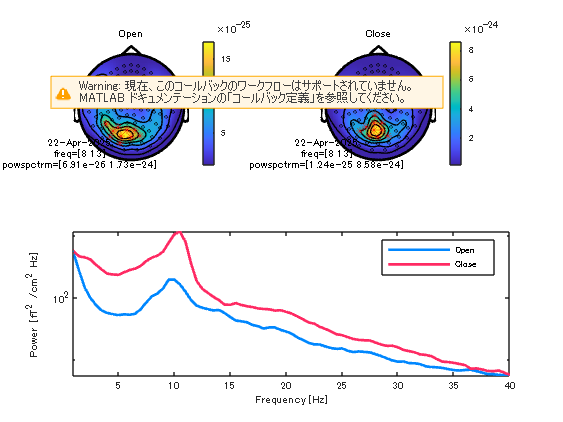

title('Close');
%% 選択されたセンサにわたって平均したパワースペクトルを描画
aveFFT_o = mean(FFT_o_cmb.powspctrm(Target_ch_o,:))*10^26; % [T 2 /m 2 Hz] -> [fT 2 /cm 2 Hz]
aveFFT_c = mean(FFT_c_cmb.powspctrm(Target_ch_c,:))*10^26; % [T 2 /m 2 Hz] -> [fT2 /cm 2 Hz]
subplot(2,1,2)
semilogy(FFT_o.freq, aveFFT_o,'Color',[0,135,255]/255,'LineWidth', 2);
hold on;
semilogy(FFT_c.freq, aveFFT_c,'Color',[255,42,99]/255,'LineWidth', 2);
xlim([1 40]);
legend('Open', 'Close')
xlabel('Frequency [Hz]');
ylabel('Power [fT^2 /cm^2 Hz]');


'Maximam power and index of open eyes'

ans = 'Maximam power and index of open eyes'

[power, freq] = max(aveFFT_o(8<=FFT_o_cmb.freq&FFT_o_cmb.freq<13));
power

power = 191.8970

freq = FFT_o_cmb.freq(find((8<=FFT_o_cmb.freq&FFT_o_cmb.freq<13),1)+freq-1)

freq = 10

'Maximam power and index of closed eyes'

ans = 'Maximam power and index of closed eyes'

[power, freq] = max(aveFFT_c(8<=FFT_c_cmb.freq&FFT_c_cmb.freq<13));
power

power = 1.1476e+03

freq = FFT_c_cmb.freq(find((8<=FFT_c_cmb.freq&FFT_c_cmb.freq<13),1)+freq-1)

freq = 10.5000